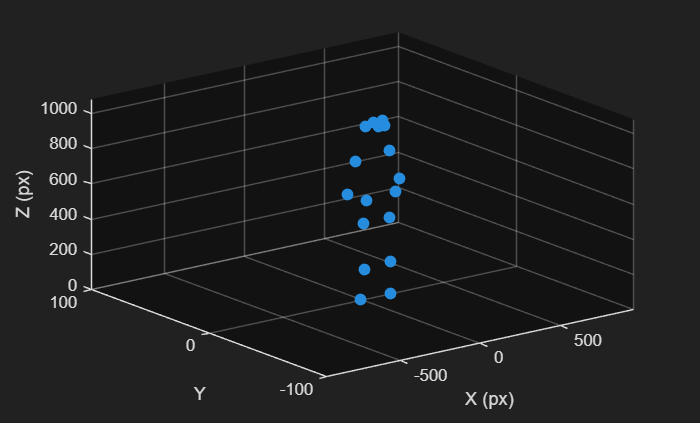

% clc; clf; clear;
%peopleDet = peopleDetector("small-network");

keyPtDetector = hrnetObjectKeypointDetector;
keyPtDetector.Threshold = 0.5;
%peopleDet = peopleDetector("small-network");

cam = webcam(2);

tracker = trackerGNN(MaxNumSensors=1, MaxNumTracks=10);
tracker.ConfirmationThreshold = [2 5];
tracker.DeletionThreshold = [5 5];
tracker.AssignmentThreshold = 30 * [5 inf];

resStr = cam.Resolution;
dims = sscanf(resStr, '%dx%d');
frameSize = [dims(2) dims(1)];  % [alto, ancho]

frecuencia = 10;
frameRate = frecuencia;
tracker.FilterInitializationFcn = @(detection) initvisionbboxkf(detection, FrameRate=frameRate, FrameSize=frameSize);

skipFrame = 2;
detectionThreshold = 0.5;
minDetectionSize = [5 5];

player = vision.VideoPlayer('Position', [20 400 700 400]);
frameCount = 0;

% Crear figura 3D
figure('Name', 'Keypoints 3D View');
ax3D = axes;
grid on;
axis([-frameSize(2)/2, frameSize(2)/2, -100, 100, 0, frameSize(1)]);
xlabel('X (px)');
ylabel('Y');
zlabel('Z (px)');
view(3);
hold on;

while true
    frame = snapshot(cam);
    frameCount = frameCount + 1;

    % 1. Detección de personas
    bboxes = helperDetectObjects(peopleDet, frame, detectionThreshold, frameCount, skipFrame, minDetectionSize);

    % 2. Seguimiento
    [trackBboxes, labels] = helperTrackBoundingBoxes(tracker, frameRate, frameCount, bboxes);

    % 3. Detección de keypoints
    [keypoints, validity] = helperDetectKeypointsUsingHRNet(frame, keyPtDetector, trackBboxes);

    % 4. Mostrar video
    frame = helperDisplayResults(frame, keyPtDetector.KeypointConnections, keypoints, validity, trackBboxes, labels, frameCount);
    player(frame);

    % 5. Visualización 3D de keypoints (sin robot)
    cla(ax3D);
    hold on;

    if ~isempty(validity)
        numPersonas = size(validity, 2);
        for i = 1:numPersonas
            personKps = keypoints(:, :, i); % (17 x 2)
            validPts = validity(:, i);

            x = personKps(validPts, 1) - frameSize(2)/2;
            y = zeros(sum(validPts), 1);  % Y fijo
            z = frameSize(1) - personKps(validPts, 2); % invertir altura (corregir persona de cabeza)

            scatter3(ax3D, x, y, z, 50, 'filled');
        end
    end

    drawnow;
    pause(0.001);
end